*****This file is for testing each filter**

clear
clc
addpath("srcs\all_func\")

Import

imgs = imageDatastore("srcs/imgs", "IncludeSubfolders", false);
n = numel(imgs.Files);

n = 13

Apply Filter

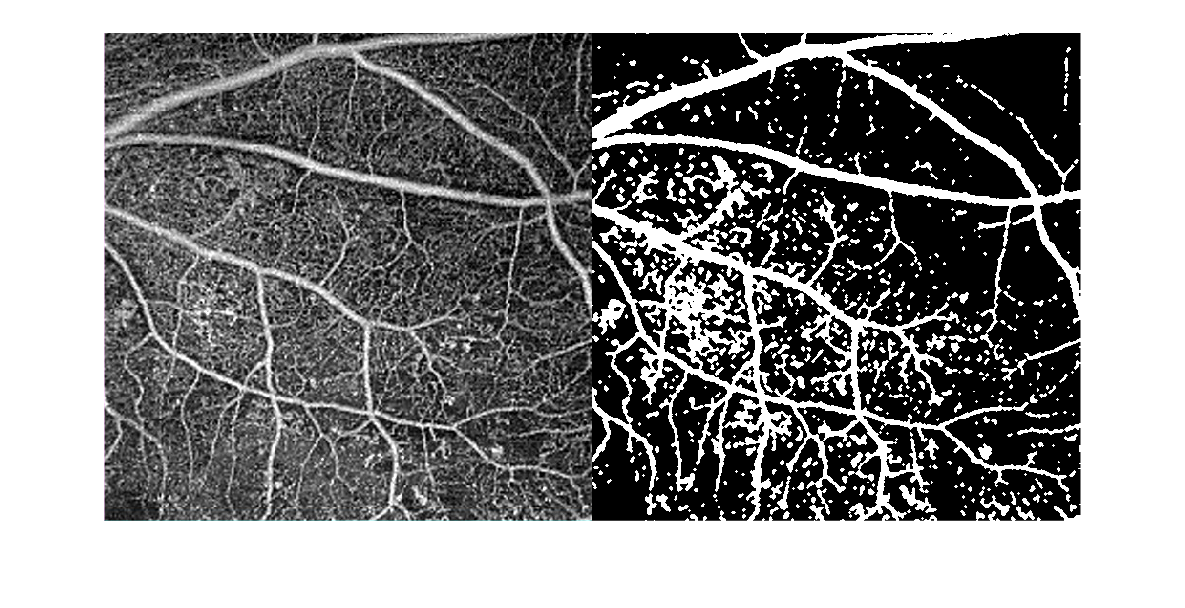

%test_img = imgs.read;
test_img = readimage(imgs, 1);
res = AllFilters.wienerFilter(test_img);
res = AllFilters.imClose(res);
%res = imbinarize(res,"adaptive");

%Compare with original
imshowpair(test_img, res, 'montage')

Comparision between filter

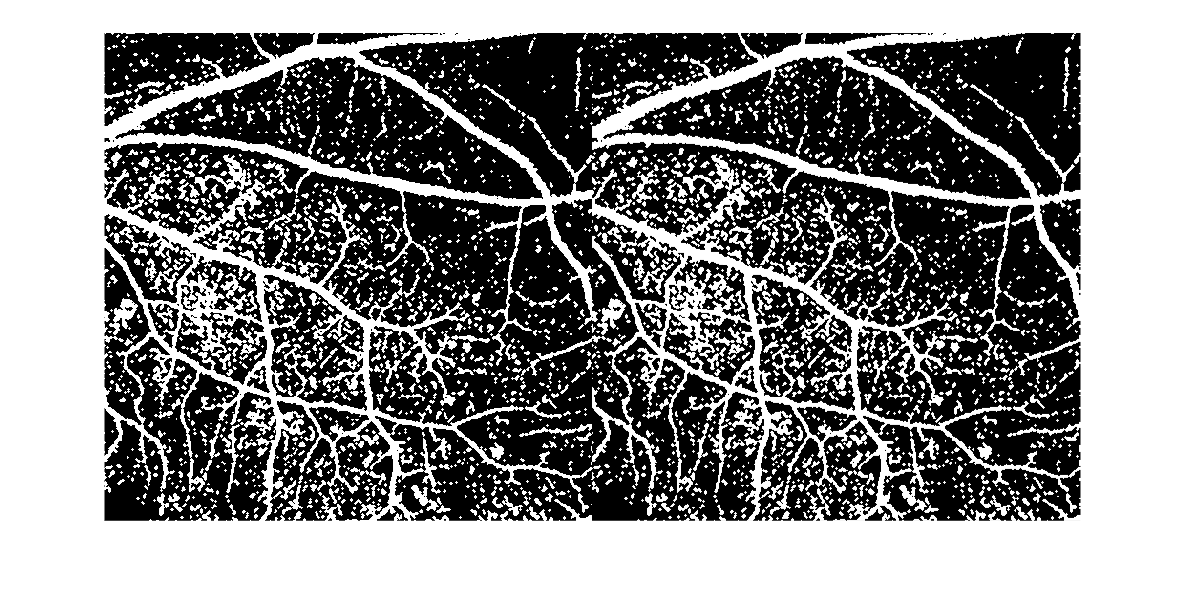

func1 = @AllFilters.imClose;
func2 = @AllFilters.wienerFilter;
func2w1 = @(img) func2(func1(img));

compare_filt(func1, func2w1, test_img);

Removed added path before End

%rmpath("srcs\all_func\")